# Practice Working with Strings

In this reading you'll see two more examples of working with text. 

- Using text of a known structure to load data and annotate figures

- Counting the occurrence of specific words in unstructured text

## Working with text of a known structure

Look at the folder containing the flights data. Notice that the files containing the detailed info for each flight all have the same format; the word "flights" is followed by the three-letter month abbreviation and the file extension. You can use this information to make examining data from different months easier.

#### Create filename and load data

The drop-down menu interactive control is used here to select a month and create a string variable containing the three-letter abbreviation for that month. The "Item Labels" are labels in the drop-down menu. The "Item Values" are the corresponding values of the string variable.

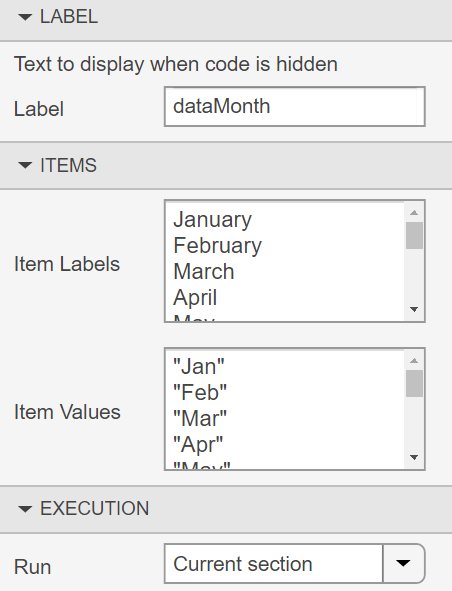

dataMonth = "Jan"

dataMonth = "Jan"

Use the selected month to create the filename and load the data. Notice that you can "add" strings together to create a new string, in this case the entire filename.

filename = "flights" + dataMonth + ".csv"

filename = "flightsJan.csv"

flights = importFlightsData(filename)

flights = 469968×20 table
         AIRLINE         TAIL_NUMBER    FLIGHT_NUMBER    ORIGIN    DESTINATION    SCHEDULED_DEPARTURE_TIME    ACTUAL_DEPARTURE_TIME    DEPARTURE_DELAY    TAXI_OUT    AIR_TIME    TAXI_IN    SCHEDULED_ARRIVAL_TIME    ACTUAL_ARRIVAL_TIME     ARRIVAL_DELAY    SCHEDULED_ELAPSED_TIME    ACTUAL_ELAPSED_TIME    DISTANCE    CANCELLED    CANCELLATION_CODE    DIVERTED
    _________________    ___________    _____________    ______    ___________    ________________________    _____________________    ____________

#### Generate Figure Title and Annotation with String Variables

Titles and annotations are helpful for interpreting figures. Rather than use a generic title, or update a title manually for every file, you can use text variables to update figure titles. You can also generate unique annotations with code so that you don't need to annotate a plot manually each time.

Create a bar plot of cancellations/day. This is similar to "Exploring the Flights Dataset" video from Week 1.

cancelled = flights(flights.CANCELLED == 1, :);
dailyCancellations = groupsummary(cancelled, "SCHEDULED_DEPARTURE_TIME", "day");
bar(dailyCancellations.GroupCount)

Use the variable dataMonth to include the month in the title.

title("Daily Cancellations in " + dataMonth)
ylabel("Number of Cancellations")

You can also combine numbers with text. The data type conversion is done automatically. The code below finds the day with the most cancellations and creates a string variable to add to the figure. Notice the use of TeX markup to create an arrow.  

[maxval, maxday] = max(dailyCancellations.GroupCount);
txt = "\leftarrow" + maxval + " cancellations";

Use the text function to add an annotation. The annotation is placed at the x-y coordinates specified by the first two arguments.

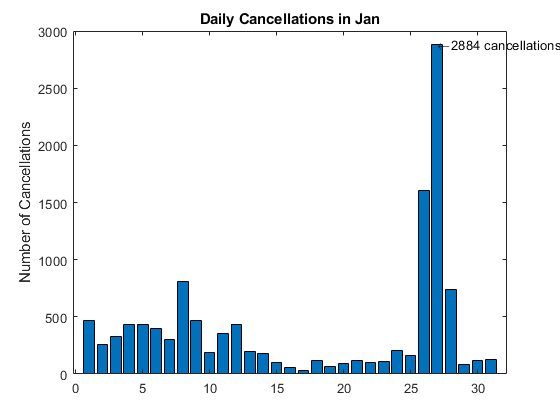

text(maxday, maxval, txt)

#### Extracting Text from a String Variable

The `extractBefore`, `extractAfter`, and `extractBetween` functions are useful functions for manipulating string variables. For example, suppose that instead of creating the filename as shown above, you had a list of filenames. This would happen if you created a datastore to work with multiple files, which you'll learn more about later. Using the flights data as an example, how could you get the month from a list of filenames?

fnames = ["flightsJan.csv"; "flightsFeb.csv"; "flightsMar.csv";...
    "flightsApr.csv"; "flightsMay.csv"; "flightsJun.csv"; "flightsJul.csv";...
    "flightsAug.csv"; "flightsSep.csv"; "flightsOct.csv"; "flightsNov.csv";...
    "flightsDec.csv";]

fnames = 12×1 string array
    "flightsJan.csv"
    "flightsFeb.csv"
    "flightsMar.csv"
    "flightsApr.csv"
    "flightsMay.csv"
    "flightsJun.csv"
    "flightsJul.csv"
    "flightsAug.csv"
    "flightsSep.csv"
    "flightsOct.csv"
    "flightsNov.csv"
    "flightsDec.csv"


% Extract the month
mnth = extractBetween(fnames, "flights", ".csv")    

mnth = 12×1 string array
    "Jan"
    "Feb"
    "Mar"
    "Apr"
    "May"
    "Jun"
    "Jul"
    "Aug"
    "Sep"
    "Oct"
    "Nov"
    "Dec"


## Unstructured Text

Later in this course, you'll use Feature Engineering to analyze Shakespeare's sonnets. However, using a few functions for working with strings, you can start to gain some insight into the sonnets. In Module 5 you'll learn how to take a text file containing all 154 of Shakespeare's sonnets and create a string array where each element in the array is an individual sonnet. The code below does this for you and displays the first sonnet.

sonnets = extractFileText("sonnets.txt");
% Split the file as there are two newline characters after each sonnet
sonnetsChunks = split(sonnets,[newline newline]);

% The Roman numerals used to number the sonnets are individual elements in
% the array - remove them by specifying a minimum length
sonnetChunkLengths = strlength(sonnetsChunks);
sonnets = sonnetsChunks(sonnetChunkLengths >= 300);

% View the first sonnet
sonnets(1)

ans =     "  From fairest creatures we desire increase,
       That thereby beauty's rose might never die,
       But as the riper should by time decease,
       His tender heir might bear his memory:
       But thou, contracted to thine own bright eyes,
       Feed'st thy light's flame with self-substantial fuel,
       Making a famine where abundance lies,
       Thy self thy foe, to thy sweet self too cruel:
       Thou that art now the world's fresh ornament,
       And only herald to the gaudy spring,
       Within thine own bud buriest thy content,
       And tender churl mak'st waste in niggarding:
         Pity the world, or else this glutton be,
         To eat the world's due, by the grave and thee."


#### Counting the occurrences of words

In the video for this lesson you used the `contains` function to return a logical array. This is sufficient for determining if a substring is present inside another. The `count` function will tell you how many times a substring appears in a string. Use the `count` function to determine how many times "love" appears in each sonnet. Many string functions include an option to "`IngoreCase`" which is used here. 

Try counting the occurrences of "love" without the "`IgnoreCase`" being true. Is there a difference?

loveCounts = count(sonnets, "love", "IgnoreCase", true)

loveCounts =      0
     0
     2
     1
     1
     0
     0
     0
     1
     3


The `nnz` function returns the number of non-zero elements in an array. Here, that is the number of sonnets that contain the word "love."

sonnetsWithLove = nnz(loveCounts)

sonnetsWithLove = 98

Summing the output of the `count` function will return the total number of times "love" occurs in the sonnets.

totalLove = sum(loveCounts)

totalLove = 220

The code below finds the sonnet where the word "love" appears the most times and displays the sonnet.

[maxLove, loveSonnet] = max(loveCounts)

maxLove = 10

loveSonnet = 40

sonnets(loveSonnet)

ans =     "  Take all my loves, my love, yea take them all;
       What hast thou then more than thou hadst before?
       No love, my love, that thou mayst true love call;
       All mine was thine, before thou hadst this more.
       Then, if for my love, thou my love receivest,
       I cannot blame thee, for my love thou usest;
       But yet be blam'd, if thou thy self deceivest
       By wilful taste of what thyself refusest.
       I do forgive thy robbery, gentle thief,
       Although thou steal thee all my poverty:
       And yet, love knows it is a greater grief
       To bear love's wrong, than hate's known injury.
         Lascivious grace, in whom all ill well shows,
         Kill me with spites yet we must not be foes."


#### Changing case and counting multiple words

It is common to ignore case when analyzing text. Instead of always adding the option to ignore case, you can make the entire string lower case or upper case using the `lower` and `upper` function respectively.

sonnets = lower(sonnets);
% View the sonnet with the most occurance of love in lower-case
sonnets(loveSonnet)

ans =     "  take all my loves, my love, yea take them all;
       what hast thou then more than thou hadst before?
       no love, my love, that thou mayst true love call;
       all mine was thine, before thou hadst this more.
       then, if for my love, thou my love receivest,
       i cannot blame thee, for my love thou usest;
       but yet be blam'd, if thou thy self deceivest
       by wilful taste of what thyself refusest.
       i do forgive thy robbery, gentle thief,
       although thou steal thee all my poverty:
       and yet, love knows it is a greater grief
       to bear love's wrong, than hate's known injury.
         lascivious grace, in whom all ill well shows,
         kill me with spites yet we must not be foes."


Instead of counting a single word, you can pass a string array to the `count` function to sum related words or themes, like death. Repeat the analysis of above, but instead of "love" search for words related to death.

deathCounts = count(sonnets, ["death", "kill", "die", "dead"]);
sonnetsWithDeath = nnz(deathCounts)

sonnetsWithDeath = 55

totalDeath = sum(deathCounts)

totalDeath = 73

[maxDeath, deathSonnet] = max(deathCounts)

maxDeath = 3

deathSonnet = 6

sonnets(deathSonnet)

ans =     "  then let not winter's ragged hand deface,
       in thee thy summer, ere thou be distill'd:
       make sweet some vial; treasure thou some place
       with beauty's treasure ere it be self-kill'd.
       that use is not forbidden usury,
       which happies those that pay the willing loan;
       that's for thy self to breed another thee,
       or ten times happier, be it ten for one;
       ten times thy self were happier than thou art,
       if ten of thine ten times refigur'd thee:
       then what could death do if thou shouldst depart,
       leaving thee living in posterity?
         be not self-will'd, for thou art much too fair
         to be death's conquest and make worms thine heir."


## Practice Using Strings

Use this script and the space below to answer the questions isn the practice quiz on strings. 

sum(count(sonnets, 'winter', "IgnoreCase", true)) ...
> sum(count(sonnets, 'summer', "IgnoreCase", true))

ans = logical
   0


T = count(sonnets, 'summer', "IgnoreCase", true)

T =      0
     0
     0
     0
     2
     1
     0
     0
     0
     0


sum(T)

ans = 20

clearvars